# Training of Rosa Drawing Skill

**—— Will_Watson   2020-12-01**

%{ 
This is a test program for Training of Rosa Drawing Skill.
At the beginning, we generate two sets of points from two normal distributions 
and label them as cluster 1 and -1.  
%}

clear all; clc; close all;

num_points = 3; % number of points in each cluster

% generate random data using two 2D Normal distributions with 100 data points 

rng default  % For reproducibility
% https://www.mathworks.com/matlabcentral/answers/269639-what-does-command-rng-default-do

EX1 = [0, 5]; % 均值
DX1 = [2, 0; 
       0, 3]; % 协方差
   
EX2 = [5, 0]; % 均值
DX2 = [4, 0; 
       0, 1];  % 协方差
   
D1 = mvnrnd(EX1, DX1, num_points); % 产生二维高斯分布数据  num_points * 2   并不随机 ???
D2 = mvnrnd(EX2, DX2, num_points); % 产生二维高斯分布数据  num_points * 2
Data = [D1(:,1)  D1(:,2)  1*ones(num_points,1)    % 加一列 1 作为标签  size(D1,1) = num_points
        D2(:,1)  D2(:,2)  -1*ones(num_points,1)]  % 加一列 -1 作为标签 

Data =    0.760376160788442   6.493327995807944   1.000000000000000
   2.593505059473153   5.552117591122634   1.000000000000000
  -3.194491866155253   2.735017430336082   1.000000000000000
   4.132815955388633   2.769437029884877  -1.000000000000000
   5.685248933077300  -1.349886940156521  -1.000000000000000
  12.156793879451520   3.034923466331855  -1.000000000000000


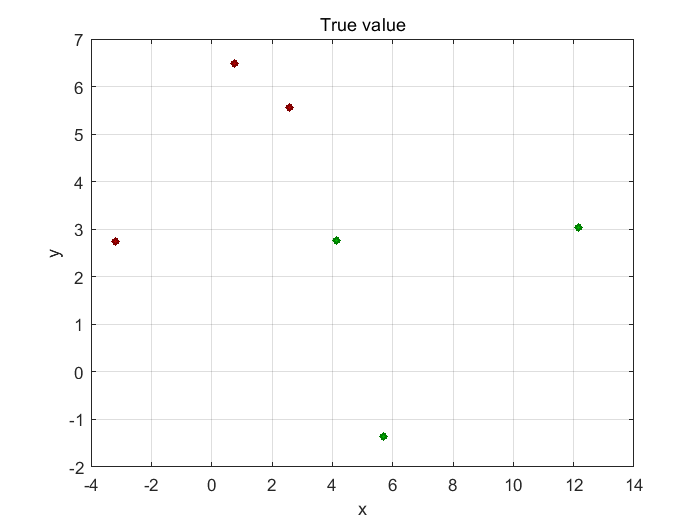

% reshuffle the data labels
%  Data_RSH = [Data(:,1:2) randi(2,2*num_points,1)];  %  取值1 2 的 [(2*num_points)*1] 单列数据 
% Uniform distribution on the set 1:2. <—— randi(2,……  X=1 2 的离散均匀分布

    
%  采用"提取-分别绘图"的方法
Data1 = Data(Data(:,3)==1, :);  % 行判断，列取值
Data2 = Data(Data(:,3)==-1, :); % 行判断，列取值
figure;  hold on;
grid on;   box on; % 加网格和边框

scatter(Data1(:,1), Data1(:,2), 10, 'MarkerEdgeColor', [0.5 0 0], 'MarkerFaceColor',[0.7 0 0], 'LineWidth',1.5);
scatter(Data2(:,1), Data2(:,2), 10, 'MarkerEdgeColor', [0 0.5 0], 'MarkerFaceColor',[0 0.7 0], 'LineWidth',1.5);
xlabel('x'); ylabel('y');title('True value');